# **Εργασία Ειδικά Συστήματα Πλοίου**

## **Ερώτημα 1: **Ανάλυση των δεδομένων με τη χρήση διαφόρων γραφικών παραστάσεων

clear all
warning("off")
% load all data
Data2024 = readtable("Data2024.csv",'TrailingDelimitersRule','ignore')

Data2024 = 451228×11 table
    Time     NOx     FuelConsumption    lambda    ExhaustGasMassFlow    IntakePressure    TorqueReference    Rot_Speed    EngineTorque    EGRCommand    ExhaustGasTemperature
    ____    _____    _______________    ______    __________________    ______________    _______________    _________    ____________    __________    _____________________

       0    167.5          2.6          7.1378            239                 4                 10            800.46          4.034           0                152.31        
    0.01    167.5          2.6          7.1378            239               

% Extract the units
% Open the file for reading
fid = fopen('Data2024.csv', 'r');
% Read the header line and discard it
fgetl(fid);
% Read the next line as a string
second_line = fgetl(fid);
% Close the file
fclose(fid);
% Split the string into cell array of units
units = strsplit(second_line, '\t');
% Convert cell array to array
units = string(units);

clearvars fid second_line ans

% Initialize the fieldnames of the data
fieldnames = Data2024.Properties.VariableNames

fieldnames = 1×11 cell array
    {'Time'}    {'NOx'}    {'FuelConsumption'}    {'lambda'}    {'ExhaustGasMassFlow'}    {'IntakePressure'}    {'TorqueReference'}    {'Rot_Speed'}    {'EngineTorque'}    {'EGRCommand'}    {'ExhaustGasTemperature'}


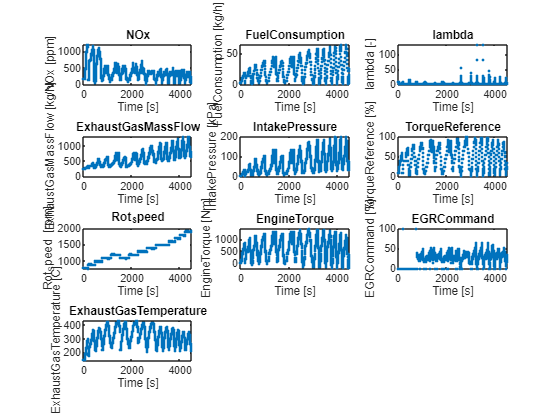

% Initialize a struct to store values
data = struct();

% Loop through each column
for i = 1:numel(fieldnames)
    % Extract values of the current column
    data.(fieldnames{i}) = table2array(Data2024(:, fieldnames{i}));
end

% Define the number of plots
num_plots = numel(fieldnames) - 1; % Excluding the first column

% Define the number of rows and columns for subplots
num_rows = ceil(sqrt(num_plots));
num_cols = ceil(num_plots / num_rows);

% Create a new figure
figure;

% Plot each column against the "Time" column on subplots
for i = 2:numel(fieldnames) % Start from the second column
    subplot(num_rows, num_cols, i-1); % Create subplot
    plot(data.Time, data.(fieldnames{i}),'.');
    title(fieldnames{i}); % Set title as column name
    xlabel('Time [s]'); % X-axis label
    ylabel(sprintf('%s %s', fieldnames{i}, units{i})); % Y-axis label
end
hold off

clearvars num_cols num_rows num_plots i ans

#### Ανάλυση Δεδομένων

% i = 2;
% figure; % Create a new figure
% plot(data.Time, data.(fieldnames{i}),".");
% title(fieldnames{i}); % Set title as column name
% xlabel('Time [s]'); % X-axis label
% 
% % Concatenate field name with unit and set it as Y-axis label
% ylabel(sprintf('%s %s', fieldnames{i}, units{i}));
% clearvars i

**NOx:** Έχουν περιοδική κίνηση με απόσβεση, φθίνουσα. Περίοδος είναι 225s. Η μέση τιμή μικραίνει με την πάροδο του χρόνου, ξεκινάει από 600 ppm και καταλήγει εως και 200 ppm.

**Fuel Consumption:** Έχουν περιοδική κίνηση με αυξανόμενο πλάτος (ίδια περίοδος με ΝΟx 180-405s η πρώτη περίοδος). Οι μέγιστες τιμές ξεκινάνε από 20kg/h και φτάνουν ως 65kg/h.

**Λάμδα:** Έχει τιμές μικρότερες του 20 εως την στιγμή 2619s που γίνεται το πρώτο peak. Έχει συνολικά 8 peaks με τα μέγιστα να ξεπερνάνε την τιμή 130.

## Ερώτημα 2: Φιλτράρισμα και μετασχηματισμός των δεδομένων.

Το παρακάτω μπορεί να χρησιμοποιηθεί για να παράγουμε τα φιλτραρισμένα δεδομένα, επιλέγοντας κάθε φορά το σωστό threshold.

% % Initialize a struct to store filtered values
% data_filt = struct();
% time_filt = struct();
% 
% % Store thresholds
% thresholds = zeros(1,length(fieldnames));
% 
% clc
% 
% for j = 2:numel(fieldnames)
%     [filteredData, filteredTime,threshold] = chauvenetFilter(Data2024,fieldnames,units,j);
%     data_filt.(fieldnames{j}) = filteredData;
%     time_filt.(fieldnames{j}) = filteredTime;
%     thresholds(1,j) = threshold;
% end
% clearvars j threshold filteredData filteredTime

#### Αποθήκευση Φιλτραρισμένων Δεδομένων

Για να αναπαράγουμε τα παραπάνω δεδομένα θα αποθηκεύσουμε τα thresholds που παράγαμε και θα μπορούμε να φορτώνουμε ξανά τα παραπάνω δεδομένα.

% writematrix(thresholds,"thresholds.csv");
% clearvars ans 

#### Ανάκτηση Δεδομένων

Για να ξαναποκτήσουμε τα φιλτραρισμένα δεδομένα, μπορούμε να τρέξουμε τον παρακάτω κώδικα:

% % Initialize a struct to store filtered values
% data_filt = struct();
% time_filt = struct();
% 
% % Read thresholds from the CSV file
% thresholds = readmatrix('thresholds.csv');
% 
% for j = 2:numel(fieldnames)
%     [filteredData, filteredTime, ~] = chauvenetFilter2(Data2024, fieldnames, units, j, thresholds(j));
%     data_filt.(fieldnames{j}) = filteredData;
%     time_filt.(fieldnames{j}) = filteredTime;
% end
% 
% clearvars filteredData filteredTime j

Μέθοδος **Interquartile Range**:

Apply to:

- Fuel Consumption (3)

- Intake Pressure (6)

- Torque Reference (7)

- Rot Speed (8)

- Engine Torque (9)

- (EGR Command(10) ->ιδιο με threshold)

- Exhaust Gas Temperature (11)

% % Initialize a struct to store filtered values
% data_filt = struct();
% time_filt = struct();
% 
% for j = 2:numel(fieldnames)
%     [filteredData,filteredTime] = IQR(Data2024.(fieldnames{j}),Data2024.Time);
%     data_filt.(fieldnames{j}) = filteredData;
%     time_filt.(fieldnames{j}) = filteredTime;
% end 
% 
% clearvars filteredData filteredTime j

Plot for **filtered data**

% i = 3;
% figure; % Create a new figure
% plot(time_filt.(fieldnames{i}),data_filt.(fieldnames{i}),".");
% title(fieldnames{i}); % Set title as column name
% xlabel('Time [s]'); % X-axis label
% 
% % Concatenate field name with unit and set it as Y-axis label
% ylabel(sprintf('%s %s', fieldnames{i}, units{i}));

**Remove outliers using median:**

use in:

- fuel consumption (3)

- exhaust mass flow (5)

- Torque Reference (7)

- Rot Speed (8)

- Engine Torque (9)

- Exhaust Gas Temperature (11)

% % Initialize a struct to store filtered values and corresponding times
% data_filt = struct();
% time_filt = struct();
% 
% i = 11;
% % Filter the data using rmoutliers
% [data_filt.(fieldnames{i}), idx] = rmoutliers(Data2024.(fieldnames{i}), "median");
% 
% % Retain corresponding times using logical indexing
% time_filt.(fieldnames{i}) = Data2024.Time;
% time_filt.(fieldnames{i})(idx) = [];
% 
% % Plot unfiltered data
% figure;
% subplot(2,1,1); % Plot on the first row, first two columns
% plot(Data2024.Time, Data2024.(fieldnames{i}),".");
% title(fieldnames{i}); % Set title as column name
% xlabel('Time [s]'); % X-axis label
% ylabel(sprintf('%s %s', fieldnames{i}, units{i})); % Concatenate field name with unit and set it as Y-axis label
% 
% % Plot unfiltered data
% subplot(2,1,2); % Plot on the second row, first column
% plot(time_filt.(fieldnames{i}),data_filt.(fieldnames{i}),".");
% title(fieldnames{i}); % Set title as column name
% xlabel('Time [s]'); % X-axis label
% ylabel(sprintf('%s %s', fieldnames{i}, units{i})); % Concatenate field name with unit and set it as Y-axis label

**Τελικό φιλτράρισμα:**

% % Initialize a struct to store filtered values
% data_filt = struct();
% time_filt = struct();
% 
% % Read thresholds from the CSV file
% thresholds = readmatrix('thresholds.csv');
% 
% for j = 2:numel(fieldnames)
%     if j == 2 || j == 4 || j == 10
%         [filteredData, filteredTime] = chauvenetFilter2(Data2024, fieldnames, units, j, thresholds(j));
%         % Calculate removedIndices based on original and filtered data
%         removedIndices = find(~ismember(Data2024.Time, filteredTime));
%         data_filt.(fieldnames{j}) = filteredData;
%         time_filt.(fieldnames{j}) = filteredTime;
%         removedTimes = unique(Data2024.Time(removedIndices));
%         time_filt.removed.(fieldnames{j}) = removedTimes;
%         % Remove corresponding data
%         Data2024(removedIndices,:) = [];
%     elseif j == 3 || j == 6 || j == 7
%         [filteredData, filteredTime] = IQR(Data2024.(fieldnames{j}), Data2024.Time);
%         % Calculate removedIndices based on original and filtered data
%         removedIndices = find(~ismember(Data2024.Time, filteredTime));
%         data_filt.(fieldnames{j}) = filteredData;
%         time_filt.(fieldnames{j}) = filteredTime;
%         removedTimes = unique(Data2024.Time(removedIndices));
%         time_filt.removed.(fieldnames{j}) = removedTimes;
%         % Remove corresponding data
%         Data2024(removedIndices,:) = [];
%     elseif j == 5 || j == 8 || j == 9 || j == 11
%         % Filter the data using rmoutliers
%         [data_filt.(fieldnames{j}), idx] = rmoutliers(Data2024.(fieldnames{j}), "median");
%         % Retain corresponding times using logical indexing
%         time_filt.(fieldnames{j}) = Data2024.Time;
%         removedIndices = idx;
%         removedTimes = unique(Data2024.Time(removedIndices));
%         time_filt.removed.(fieldnames{j}) = removedTimes;
%         % Remove corresponding data
%         Data2024(removedIndices,:) = [];
%     end
% end
% 
% clearvars data_filt filteredData filteredTime idx j removedIndices removedTimes thresholds time_filt

% % Save training and testing structs to files
% filtered_data_file = 'filtered_data.mat';
% save(filtered_data_file, 'Data2024');
% % plot_differences(Data2024,fieldnames,units,data_filt,time_filt,4)

#### **Κανονικοποίηση Δεδομένων:**

% i = 8;
% fieldname = fieldnames{i};
% % Normalize Data
% [normalizedTable,centerValue,scaleValue] = normalize(filtered_data,"range");
% 
% % Display results
% figure
% tiledlayout(2,1);
% nexttile
% plot(filtered_data.(fieldnames{i}),"Color",[77 190 238]/255,"DisplayName","Input data")
% legend
% ylabel(fieldnames{i})
% 
% nexttile
% plot(newTable.(fieldnames{i}),"Color",[0 114 189]/255,"LineWidth",1.5,...
%     "DisplayName","Normalized data")
% legend
% ylabel(fieldnames{i})
% set(gcf,"NextPlot","New")

### Χωρισμός Δεδομένων:

% % Initialize structs to store training and testing data
% training = struct();
% testing = struct();
% 
% for i = 1:numel(fieldnames)
%     % Define the percentage of data for training and testing
%     train_percent = 0.8;
%     test_percent = 1 - train_percent;
% 
%     % Get the field name
%     fieldname = fieldnames{i};
% 
%     % Extract the data directly from Data2024
%     data2 = normalizedTable.(fieldname);
%     times2 = normalizedTable.Time;
% 
%     % Create indices for cross-validation with 80% training and 20% testing
%     cv = cvpartition(size(data2, 1), 'Holdout', test_percent);
% 
%     % Get indices for training and testing sets
%     train_idx = cv.training;
%     test_idx = cv.test;
% 
%     % Split the data into training and testing sets
%     training.(fieldname) = data2(train_idx, :);
%     testing.(fieldname) = data2(test_idx, :);
% end
% 
% % Define file paths for saving
% training_file = 'training_data-normalized.mat';  % Specify the file path for saving training data
% testing_file = 'testing_data-normalized.mat';    % Specify the file path for saving testing data
% 
% % Save training and testing structs to files
% save(training_file, 'training');
% save(testing_file, 'testing');

% % Initialize structs to store training and validating data
% training2 = struct();
% validating = struct();
% 
% for i = 1:numel(fieldnames)
%     % Define the percentage of data for training and testing
%     train_percent = 0.8;
%     val_percent = 1 - train_percent;
% 
%     % Get the field name
%     fieldname = fieldnames{i};
% 
%     % Extract the data and corresponding times corresponding to the field name
%     data2 = training.(fieldname);
%     times2 = training.Time;
% 
%     % Create indices for cross-validation with 80% training and 20% testing
%     cv = cvpartition(size(data2, 1), 'Holdout', val_percent);
% 
%     % Get indices for training and testing sets
%     train_idx = cv.training;
%     val_idx = cv.test;
% 
%     % Split the data into training and testing sets
%     training2.(fieldname) = data2(train_idx, :);
%     validating.(fieldname) = data2(val_idx, :);
% end
% 
% % Define file paths for saving
% training_file = 'training2_data-normalized.mat';  % Specify the file path for saving training data
% validating_file = 'validating_data-normalized.mat';    % Specify the file path for saving testing data
% 
% % Save training and validating structs to files
% save(training_file, 'training2');
% save(validating_file, 'validating');


**To check the separation was ok:**

% i = 5;
% 
% % Plot unfiltered data
% figure;
% subplot(2,1,1); % Plot on the first row, first two columns
% plot(Data2024.Time, Data2024.(fieldnames{i}), ".");
% title(fieldnames{i}); % Set title as column name
% xlabel('Time [s]'); % X-axis label
% ylabel(sprintf('%s %s', fieldnames{i}, units{i})); % Concatenate field name with unit and set it as Y-axis label
% 
% % Plot filtered data
% subplot(2,1,2); % Plot on the second row, first column
% plot(testing.Time, testing.(fieldnames{i}), ".");
% title(['Filtered ' fieldnames{i}]);
% xlabel('Time [s]'); % X-axis label
% ylabel(sprintf('%s %s', fieldnames{i}, units{i})); % Concatenate field name with unit and set it as Y-axis label
% clearvars i

**Load previewsly made training and testing data:**

% % Load previewsly filtered Data
% filtered_data = load("filtered_data.mat");
% filtered_data = filtered_data.Data2024
% % Load the training data from the .mat file
% training = load('training2_data.mat');
% training = struct2table(training.training2)
% % Load the testing data from the .mat file
% testing = load('testing_data.mat');
% testing = struct2table(testing.testing)
% % Load the validating data from the .mat file
% validating = load('validating_data.mat');
% validating = struct2table(validating.validating)

**Load previewsly made training and testing data:**

% Load previewsly filtered Data
filtered_data = load("normalized_table.mat");
filtered_data = filtered_data.normalizedTable
% filtered_data = filtered_data.Data2024
% Load the training data from the .mat file
training = load('training2_data-normalized.mat');
training = struct2table(training.training2)
% Load the testing data from the .mat file
testing = load('testing_data-normalized.mat');
testing = struct2table(testing.testing)
% Load the validating data from the .mat file
validating = load('validating_data-normalized.mat');
validating = struct2table(validating.validating)

#### Correlation Matrix

% Convert the table to a matrix
dataMatrix = table2array(filtered_data);
correlationMatrix = corr(dataMatrix)
figure;

% Plot the heatmap
h = heatmap(filtered_data.Properties.VariableNames, filtered_data.Properties.VariableNames, correlationMatrix);

% Customize the heatmap
h.Title = 'Correlation Matrix';
h.XLabel = 'Variables';
h.YLabel = 'Variables';

### Εκπαίδευση Νευρωνικού

Πρώτα πρέπει να μετατρέψουμε τα δεδομένα μας σε datastores

% Initialize the datastore with the first field
training_ds = arrayDatastore(training.(fieldnames{1}));
validating_ds = arrayDatastore(validating.(fieldnames{1}));

filtered_data = 440726×11 table
       Time         NOx      FuelConsumption    lambda     ExhaustGasMassFlow    IntakePressure    TorqueReference    Rot_Speed    EngineTorque    EGRCommand    ExhaustGasTemperature
    __________    _______    _______________    _______    __________________    ______________    _______________    _________    ____________    __________    _____________________

             0    0.12214       0.029412        0.46948        0.0015026            0.010204          0.072165        0.011555       0.11773           0                0.02435       
    2.2162e-06    0.12214       0.029412    


% Loop through the remaining fields and combine datastores
for i = 2:numel(fieldnames)
    add_train_ds = arrayDatastore(training.(fieldnames{i}));

training = 282065×11 table
       Time         NOx      FuelConsumption    lambda     ExhaustGasMassFlow    IntakePressure    TorqueReference    Rot_Speed    EngineTorque    EGRCommand    ExhaustGasTemperature
    __________    _______    _______________    _______    __________________    ______________    _______________    _________    ____________    __________    _____________________

             0    0.12214       0.029412        0.46948        0.0015026            0.010204          0.072165        0.011555       0.11773           0                0.02435       
    2.2162e-06    0.12214       0.029412        0

    training_ds = combine(training_ds, add_train_ds);

    add_val_ds = arrayDatastore(validating.(fieldnames{i}));

testing = 88145×11 table
       Time         NOx      FuelConsumption    lambda     ExhaustGasMassFlow    IntakePressure    TorqueReference    Rot_Speed    EngineTorque    EGRCommand    ExhaustGasTemperature
    __________    _______    _______________    _______    __________________    ______________    _______________    _________    ____________    __________    _____________________

    1.7729e-05    0.12214       0.029412        0.46948        0.0022539            0.010204          0.072165        0.011854       0.11761           0                0.02435       
    2.6594e-05    0.12214       0.029412        0.4

    validating_ds = combine(validating_ds, add_val_ds);
end


validating = 70516×11 table
       Time         NOx      FuelConsumption    lambda     ExhaustGasMassFlow    IntakePressure    TorqueReference    Rot_Speed    EngineTorque    EGRCommand    ExhaustGasTemperature
    __________    _______    _______________    _______    __________________    ______________    _______________    _________    ____________    __________    _____________________

    4.4324e-06    0.12214       0.029412        0.47144        0.0015026            0.010204          0.072165         0.011748      0.11857           0                0.02435       
    1.3297e-05    0.12173       0.029412        

clearvars add_train_ds add_val_ds i 

### Functions

Για την επιλογή των **thresholds**:

function [filteredData, filteredTime, threshold] = chauvenetFilter(Data, fieldnames, units, i)


correlationMatrix =     1.0000   -0.4677    0.4131    0.0255    0.7597    0.5120    0.1556    0.9720    0.0895    0.5116    0.0772
   -0.4677    1.0000    0.2195   -0.5277   -0.0892    0.1171    0.4302   -0.4440    0.4605   -0.1871    0.2511
    0.4131    0.2195    1.0000   -0.6551    0.8760    0.9774    0.9471    0.4164    0.9260    0.7279    0.6301
    0.0255   -0.5277   -0.6551    1.0000   -0.3440   -0.5174   -0.7510    0.0074   -0.7562   -0.5799   -0.5404
    0.7597   -0.0892    0.8760   -0.3440    1.0000    0.9348    0.6942    0.7702    0.6468    0.6686    0.4086
    0.5120    0.1171    0.9774   -0.5174    0.9348    1.0000    0.8860    0.5079    0.8610    0.6897    0.6032
    0.1556    0.4302    0.9471   -0.7510    0.6942    0.8860    1.0000    0.1528    0.9958    0.6386    0.7123
    0.9720   -0.4440    0.4164    0.0074    0.7702    0.5079    0.1528    1.0000    0.0814    0.5052    0.0272
    0.0895    0.4605    0.9260   -0.7562    0.6468    0.8610    0.9958    0.0814    1.0000  

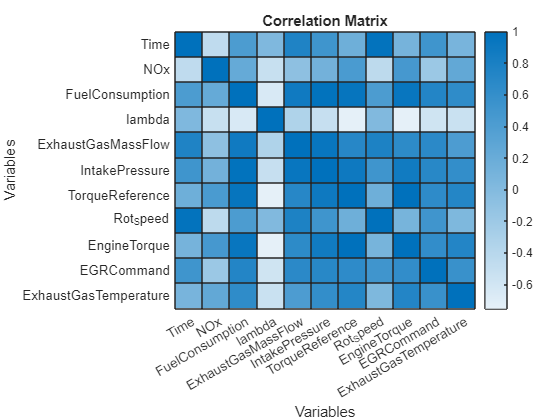

    data = Data.(fieldnames{i});
    time = Data.Time;
    
    redo = true;
    while redo
        % Calculate mean and standard deviation
        mu = mean(data);
        sigma = std(data);


        % Calculate residuals
        residuals = abs(data - mu);

        % Calculate probability
        p = 1 - 0.5 * (1 + erf(residuals / (sigma * sqrt(2))));
        p_mean = mean(p);
        
        % Plot unfiltered data
        figure;
        subplot(2,2,1); % Plot on the first row, first two columns
        plot(time, data);
        title(fieldnames{i}); % Set title as column name
        xlabel('Time [s]'); % X-axis label
        ylabel(sprintf('%s %s', fieldnames{i}, units{i})); % Concatenate field name with unit and set it as Y-axis label

        % Plot unfiltered data
        subplot(2,2,2); % Plot on the second row, first column
        plot(time, data,".");
        title(fieldnames{i}); % Set title as column name
        xlabel('Time [s]'); % X-axis label
        ylabel(sprintf('%s %s', fieldnames{i}, units{i})); % Concatenate field name with unit and set it as Y-axis label

        % Prompt user for threshold
        threshold = input(['Enter the threshold probability (mean is ', num2str(p_mean), '): ']);

        % Apply Chauvenet's Criterion (threshold probability)
        outliers = p < threshold;

        % Remove outliers
        filteredData = data(~outliers);
        filteredTime = time(~outliers);

        % Plot filtered data
        subplot(2,2,[3,4]); % Plot on the second row, second column
        plot(filteredTime, filteredData);
        title(['Filtered ', fieldnames{i}]); % Set title as column name
        xlabel('Time [s]'); % X-axis label
        ylabel(sprintf('%s %s (Filtered)', fieldnames{i}, units{i})); % Concatenate field name with unit and set it as Y-axis label
        
        % Ask if the user wants to redo
        redo_prompt = input('Do you want to redo the filtering? (yes/no): ', 's');
        if strcmpi(redo_prompt, 'no')
            redo = false;
        end
    end
end

Για την **ανάκτηση** των φιλτραρισμένων δεδομένων:

function [filteredData, filteredTime, threshold] = chauvenetFilter2(Data, fieldnames, units, i, threshold)

    data = Data.(fieldnames{i});
    time = Data.Time;
    
    % Calculate mean and standard deviation
    mu = mean(data);
    sigma = std(data);

    % Calculate residuals
    residuals = abs(data - mu);

    % Calculate probability
    p = 1 - 0.5 * (1 + erf(residuals / (sigma * sqrt(2))));
    p_mean = mean(p);

    % Apply Chauvenet's Criterion (threshold probability)
    outliers = p < threshold;

    % Remove outliers
    filteredData = data(~outliers);
    filteredTime = time(~outliers);
end

Μέθοδος **Interquartile Range**:

[https://www.indeed.com/career-advice/career-development/outliers-statistics](https://www.indeed.com/career-advice/career-development/outliers-statistics)

function [FilteredData,Time]=IQR(Data,Time)
%% Remove outliers from vectors with interquartile range method

% Sort Input Data in ascending order 
[Data,indx]=sort(Data);

% Calculate length of Vector Input Data 
n=length(Data);

% Check if the number of Data's elements is even or odd
if mod(n,2)~=0
    % If the number is odd, split the set as explained in the oddlength
    % function
    [~,Data1,Data3,n2]=oddlength(Data,n);
    % Check if the number of the split Datas' elements is even or odd
    if mod(n2,2)~=0
        % If the number is odd, calculate the median of each split set,
        % according to the oddlength function
        Q1=oddlength(Data1,n2);
        Q3=oddlength(Data3,n2);
    else
        % If the number is even, calculate the median of each split set,
        % according to the evenlength function
        Q1=evenlength(Data1,n2);
        Q3=evenlength(Data3,n2);
    end
else
    % If the number is even, split the set as explained in the evenlength
    % function
    [~,Data1,Data3,n2]=evenlength(Data,n);
    % Check if the number of the split Datas' elements is even or odd
    if mod(n2,2)~=0
        % If the number is odd, calculate the median of each split set,
        % according to the oddlength function
        Q1=oddlength(Data1,n2);
        Q3=oddlength(Data3,n2);
    else
        % If the number is even, calculate the median of each split set,
        % according to the evenlength function
        Q1=evenlength(Data1,n2);
        Q3=evenlength(Data3,n2);
    end
end

% Calculate the value of IQR
vIQR=Q3-Q1;

% Unsort the Data
UData(indx)=Data;

% Transpose the Unsorted Data matrix
UData=transpose(UData);

% Delete the values that are outside the IQR range
idx=UData>=Q3+1.5*vIQR | UData<=Q1-1.5*vIQR;
UData(idx)=[];
Time(idx)=[];

% Save the filtered Data
FilteredData=UData;
end
function [Median,LowerSet,UpperSet,n2]=oddlength(Data,n)
%% This function calculates the Median of the Input Vector Data set, 
%% divides the set to Upper and Lower halves and calculates the length of the produced sets
%% when the number of elements is odd

% The median of an odd set is the element that divides the set into two
% sets with an equal number of elements
Median=Data((n-1)/2+1);

% The lower half of the set contains elements from the first one to the one before
% the median of the original set
LowerSet=Data(1:(n-1)/2);

% The upper half of the set contains elements from the one after
% the median to the end of the original set
UpperSet=Data((n-1)/2+2:end);

% Calculate the length of the produced sets
n2=length(LowerSet);
end
function [Median,LowerSet,UpperSet,n2]=evenlength(Data,n)
%% This function calculates the Median of the Input Vector Data set, 
%% divides the set to Upper and Lower halves and calculates the length of the produced sets
%% when the number of elements is even

% The median of an even set is the mean value of the two central elements
% that split the set to two sets with an equal number of elements
Median=(Data(n/2)+Data(n/2+1))/2;

% The lower half of the set contains elements from the first one until the
% former central element of the original set
LowerSet=Data(1:n/2);

% The upper half of the set contains elements from the first latter central element 
% until the end of the original set
UpperSet=Data(n/2+1:end);

% Calculate the length of the produced sets
n2=length(UpperSet);
end


**To plot data filtered and unfiltered:**

function plot_differences(Data2024,fieldnames,units,data_filt,time_filt,i)
    % Plot unfiltered data
    figure;
    subplot(2,1,1); % Plot on the first row, first two columns
    plot(Data2024.Time, Data2024.(fieldnames{i}),".");
    title(fieldnames{i}); % Set title as column name
    xlabel('Time [s]'); % X-axis label
    ylabel(sprintf('%s %s', fieldnames{i}, units{i})); % Concatenate field name with unit and set it as Y-axis label
    
    % Plot unfiltered data
    subplot(2,1,2); % Plot on the second row, first column
    plot(time_filt.(fieldnames{i}),data_filt.(fieldnames{i}),".");
    title(['Filtered ' fieldnames{i}]);
    xlabel('Time [s]'); % X-axis label
    ylabel(sprintf('%s %s', fieldnames{i}, units{i})); % Concatenate field name with unit and set it as Y-axis label
end